function files = randReplicateFiles(files,numDesired)
n = numel(files);
ind = randi(n,numDesired,1);
files = files(ind);
end
imds = imageDatastore("resized_dataset\", IncludeSubfolders=true, LabelSource="foldernames");
[imdsTrain, imdsTest]=splitEachLabel(imds,0.8);
%histogram(imdsTrain.Labels)
labels=imdsTrain.Labels;
[G,classes] = findgroups(labels);
numObservations = splitapply(@numel,labels,G);
desiredNumObservationsPerClass = max(numObservations);
files = splitapply(@(x){randReplicateFiles(x,desiredNumObservationsPerClass)},imdsTrain.Files,G);
files = vertcat(files{:});
labels=[];info=strfind(files,'\');
for i=1:numel(files)
    idx=info{i};
    dirName=files{i};
    targetStr=dirName(idx(end-1)+1:idx(end)-1);
    targetStr2=cellstr(targetStr);
    labels=[labels;categorical(targetStr2)];
end
imdsTrain.Files = files;
imdsTrain.Labels=labels;
%histogram(imdsTrain.Labels)
labels=imdsTest.Labels;
%histogram(labels)
[G,classes] = findgroups(labels);
numObservations = splitapply(@numel,labels,G);
desiredNumObservationsPerClass = max(numObservations);
files = splitapply(@(x){randReplicateFiles(x,desiredNumObservationsPerClass)},imdsTest.Files,G);
files = vertcat(files{:});
labels=[];info=strfind(files,'\');
for i=1:numel(files)
    idx=info{i};
    dirName=files{i};
    targetStr=dirName(idx(end-1)+1:idx(end)-1);
    targetStr2=cellstr(targetStr);
    labels=[labels;categorical(targetStr2)];
end
imdsTest.Files = files;
imdsTest.Labels=labels;
%histogram(imdsTest.Labels)

pixelRange = [-30 30];
RotationRange = [-30 30];
scaleRange = [0.8 1.2];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange, ...
    'RandRotation',RotationRange ...
    ); 
resizeTrainImgs = augmentedImageDatastore([224 224],imdsTrain, "DataAugmentation", imageAugmenter);
resizeTestImgs = augmentedImageDatastore([224 224],imdsTest, "DataAugmentation",imageAugmenter);


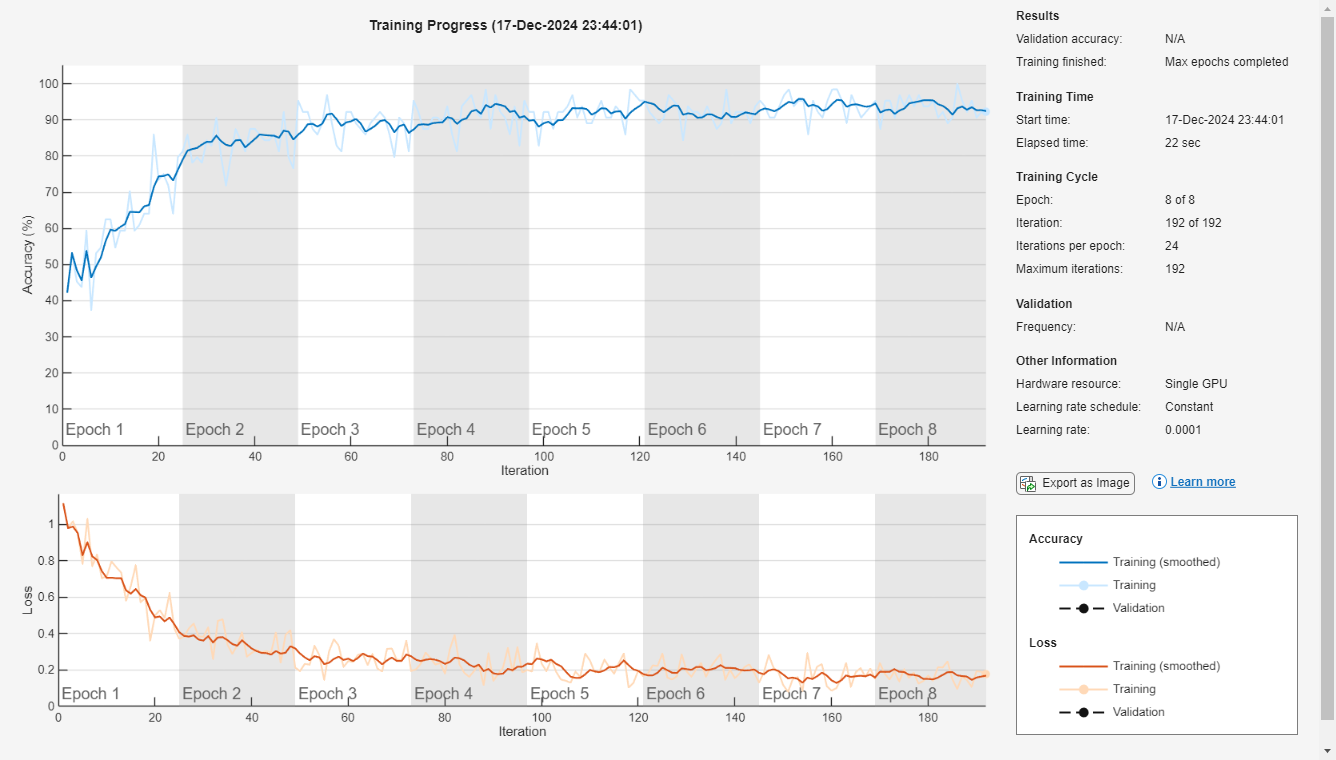

net = resnet18;
inputSize = net.Layers(1).InputSize;
lgraph = layerGraph(net);
learnableLayer='fc1000';
classLayer='ClassificationLayer_predictions';
numClasses = numel(categories(imds.Labels));
newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
lgraph = replaceLayer(lgraph,learnableLayer,newLearnableLayer);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer,newClassLayer);

miniBatchSize = 64;
valFrequency = 10;
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',8, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'Verbose',false, ...
    'Plots','training-progress');
net = trainNetwork(resizeTrainImgs,lgraph,options);

save("net.mat", "net")

[YPred,probs] = classify(net,resizeTestImgs);
accuracy = mean(YPred == imdsTest.Labels)

accuracy = 0.9242

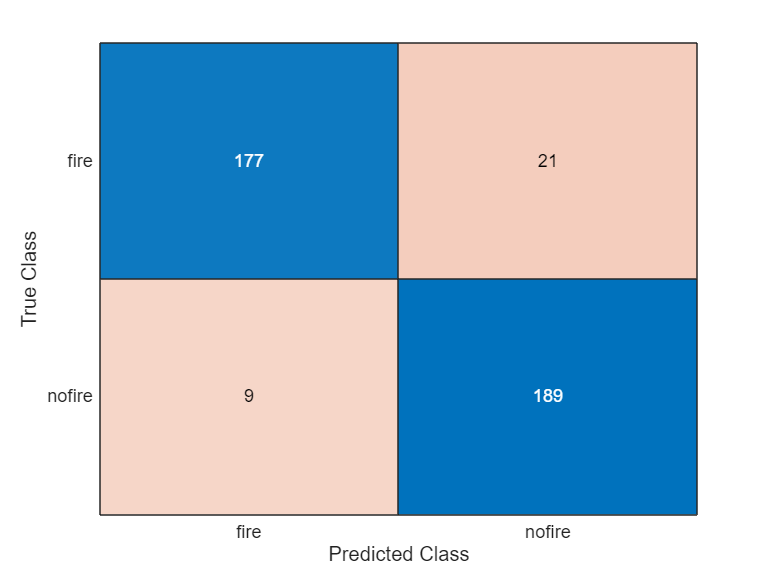

YTrue=imdsTest.Labels;
figure;cm=confusionchart(YTrue,YPred);